# Demo_SPEN_unaliasing using PSF-basd mapping matrix

This document contains the simulation of SPEN unaliasing procedure.

## Contents

- Load the data

- k space simulation including conventional (EPI k space) and (SPEN k space)

- PSF simulation

- Unaliasing SPEN images based on PSF

## Load the data

Two types of data are provided:

(1) Brain T1 image: **Data from: T1-weighted in vivo human whole brain MRI dataset with an ultrahigh isotropic resolution of 250 μm, Lüsebrink F, Sciarra A, Mattern H, Yakupov R, Speck O  **Date Published: March 10, 2017 DOI: https://doi.org/10.5061/dryad.38s74

(2) Shepp-Logan head phantom image.

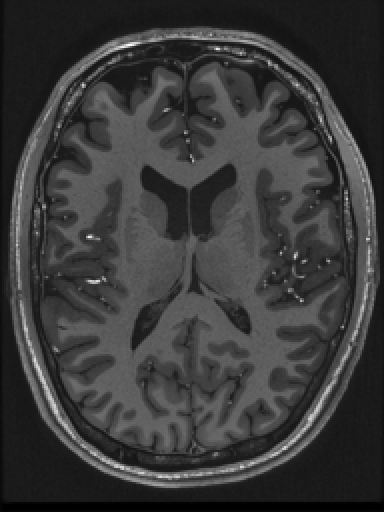

clc; clear; close all;
toolpath=genpath('tool');
addpath(toolpath);
addpath('data');
addpath('src');

%Choose either one type of data
% brain image
load im_brain_highres.mat
figure; ismrm_imshow(imresize(im,[256 192]))

% phantom image
% im = phantom(4096);
% figure();ismrm_imshow(imresize(im,[192 192]))

## k-space simulation

First generate a large k space from "high-resolution" image, then we sample from this "full" k space with different subsampling factor, here we use Nacc=[1 2 3 4]

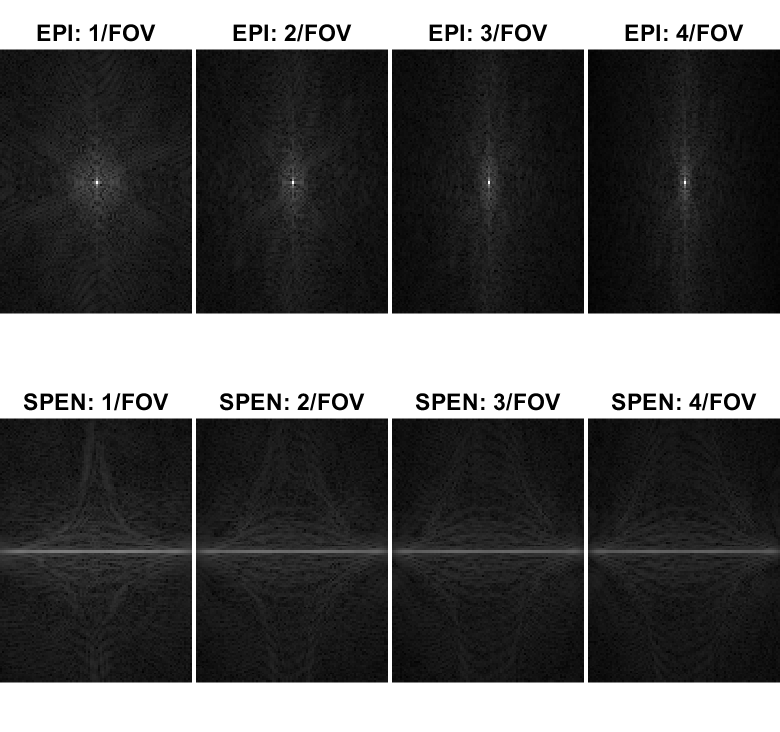

%Parameters setting
[sx,sy] = size(im);
Nacc=[1 2 3 4];
Nk=96;
FOV=200;
deltak=Nacc*1/FOV;
Q=Nacc*Nk/2/FOV^2;
ysource = (-sy/2:sy/2-1)*FOV/sy;
k_EPI_full = fft2r2k(im);
k_SPEN_full = fft2r2k(bsxfun(@times,im,permute(exp(1i*2*pi*Q.'*ysource.^2),[3 2 1])));

k_EPI=zeros(Nk*sx/sy,Nk,length(Nacc));
k_SPEN=zeros(Nk*sx/sy,Nk,length(Nacc));
txtarray_EPI=cell(1,length(Nacc));
txtarray_SPEN=cell(1,length(Nacc));
for m=1:length(Nacc)
    k_EPI(:,:,m)=crop(k_EPI_full(:,(sy/2+1)+(-Nk/2*Nacc(m):Nacc(m):(Nk/2-1)*Nacc(m))),[Nk*sx/sy,Nk]);    
    k_SPEN(:,:,m)=crop(k_SPEN_full(:,(sy/2+1)+(-Nk/2*Nacc(m):Nacc(m):(Nk/2-1)*Nacc(m)),m),[Nk*sx/sy,Nk]);
    txtarray_EPI{m}=['EPI: ',num2str(m),'/FOV'];
    txtarray_SPEN{m}=['SPEN: ',num2str(m),'/FOV'];
end

im_EPI=fft2k2r(k_EPI);
im_SPEN=fft2k2r(k_SPEN);
figure();ismrm_imshow(abs(cat(3,k_EPI,k_SPEN)).^(1/3),[],[2,length(Nacc)],cat(2,txtarray_EPI,txtarray_SPEN));

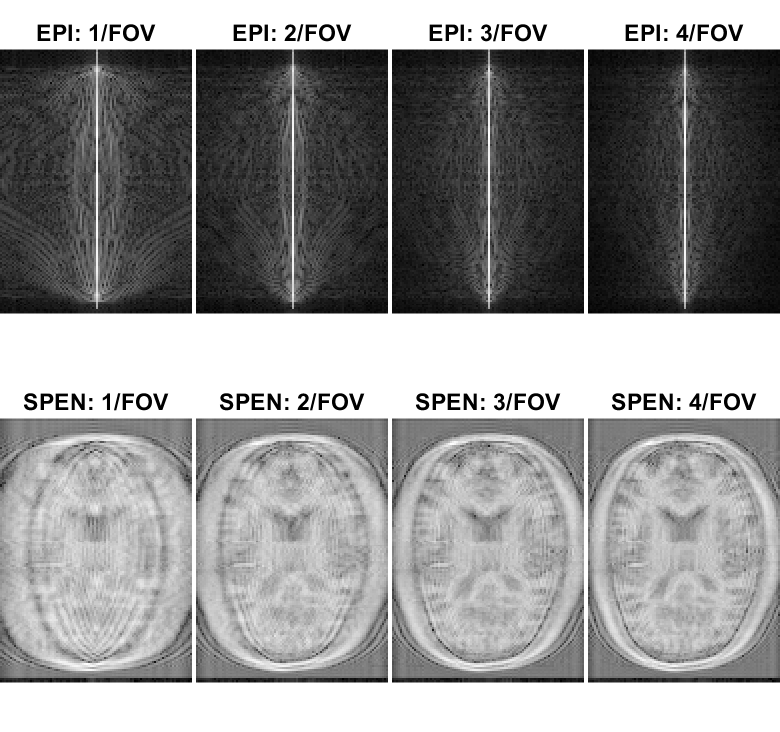

figure();ismrm_imshow(abs(fftk2r(cat(3,k_EPI,k_SPEN),[],1)).^(1/3),0,[2,length(Nacc)],cat(2,txtarray_EPI,txtarray_SPEN));

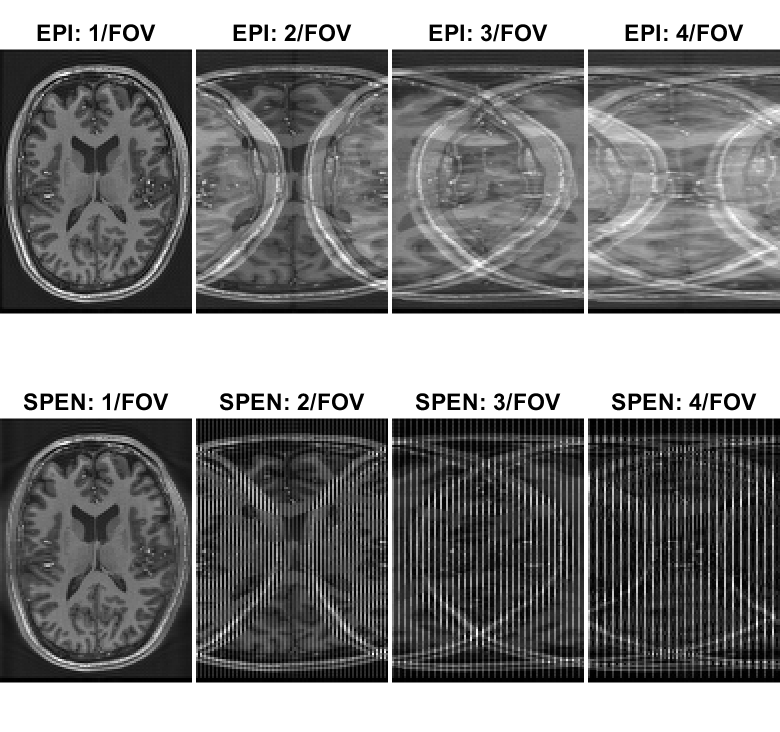

figure();ismrm_imshow(abs(cat(3,im_EPI,im_SPEN)),0,[2,length(Nacc)],cat(2,txtarray_EPI,txtarray_SPEN));

## PSF mapping from source to acquired image space

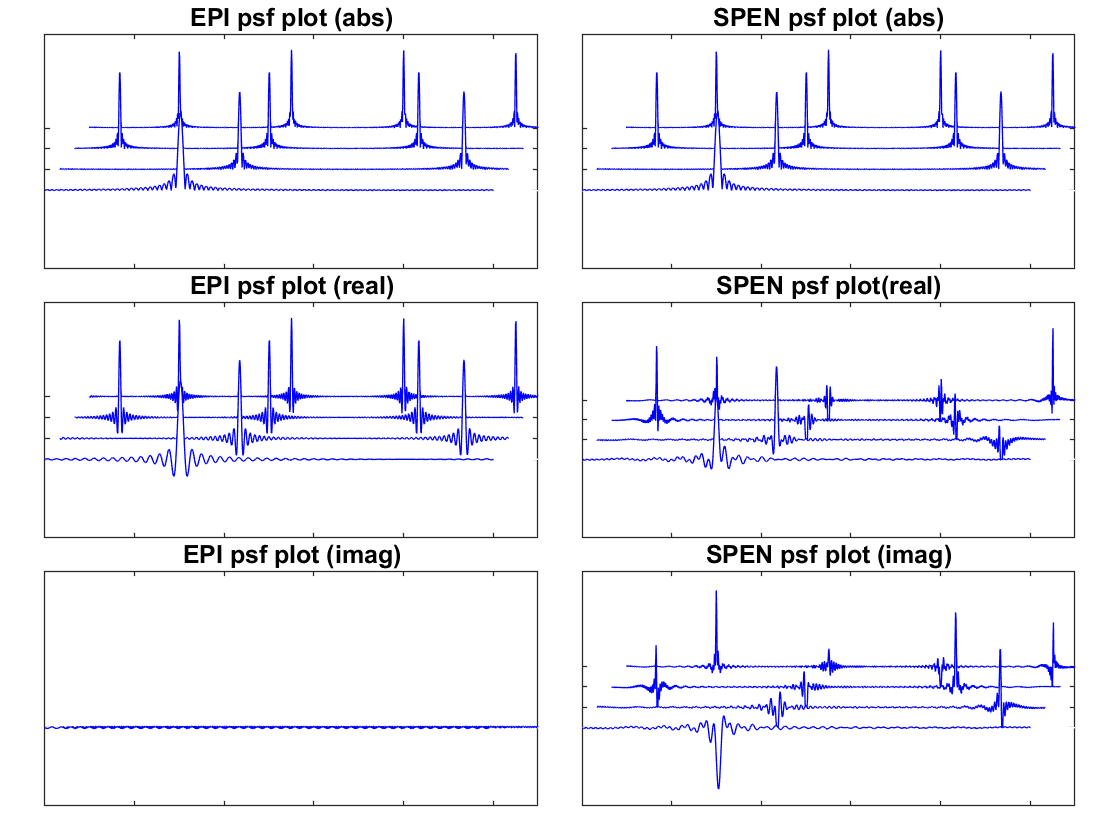

psf_map_EPI=zeros(Nk,1000,length(Nacc));
psf_map_SPEN=zeros(Nk,1000,length(Nacc));
for m=1:length(Nacc)
    y_samp=(-Nk/2:Nk/2-1)*FOV/Nacc(m)/Nk;
    y_source=linspace(-FOV/2,FOV/2,1000);
    psf_map_EPI(:,:,m)=PSF_SPEN(y_source,y_samp,deltak(m),Nk,0);
    psf_map_SPEN(:,:,m)=PSF_SPEN(y_source,y_samp,deltak(m),Nk,Q(m)); 
end
figure();
subplot_tight(3,2,1);stackedplot(squeeze(abs(psf_map_EPI(30,:,:))));ylim([-1 2]);title('EPI psf plot (abs)');
subplot_tight(3,2,3);stackedplot(squeeze(real(psf_map_EPI(30,:,:))));ylim([-1 2]);title('EPI psf plot (real)');
subplot_tight(3,2,5);stackedplot(squeeze(imag(psf_map_EPI(30,:,:))));ylim([-1 2]);title('EPI psf plot (imag)');
subplot_tight(3,2,2);stackedplot(squeeze(abs(psf_map_SPEN(30,:,:))));ylim([-1 2]);title('SPEN psf plot (abs)');
subplot_tight(3,2,4);stackedplot(squeeze(real(psf_map_SPEN(30,:,:))));ylim([-1 2]);title('SPEN psf plot(real)');
subplot_tight(3,2,6);stackedplot(squeeze(imag(psf_map_SPEN(30,:,:))));ylim([-1 2]);title('SPEN psf plot (imag)');

## Unaliasing SPEN images based on PSF

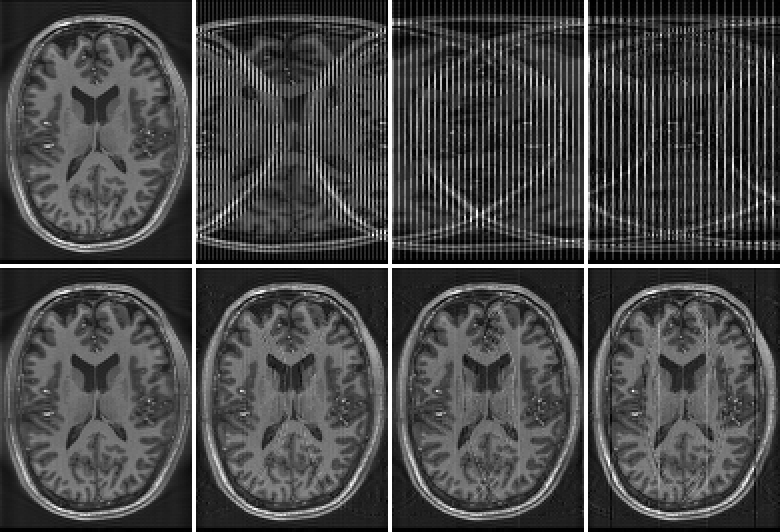

im_SPEN_unaliasing=zeros(size(im_SPEN));
for m=1:length(Nacc)
    y_samp=linspace(-FOV/2/Nacc(m),FOV/2/Nacc(m),Nk);
    y_rec=linspace(-FOV/2,FOV/2,Nk+1);
    A=A_im2im(y_rec,y_samp,Q(m),deltak(m),Nk);    
    AHA=A'*A;
    reduced_eye = diag(abs(diag(AHA))>0);
    n_alias = sum(reduced_eye(:));
    scaled_reg_factor = 1 * trace(AHA)/n_alias;
    im_SPEN_unaliasing(:,:,m)=(pinv(AHA + reduced_eye .* scaled_reg_factor) * A'*im_SPEN(:,:,m).').';
end
figure();ismrm_imshow(abs(cat(3,im_SPEN,im_SPEN_unaliasing)),0,[2 length(Nacc)]);